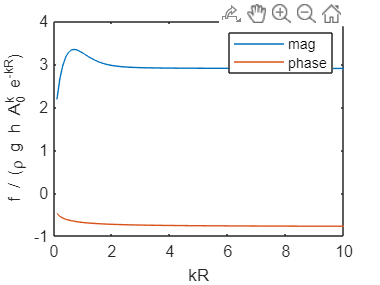

% equation 156 of Olaya paper
% https://ieeexplore.ieee.org/document/6895317/
% excitation force with heave plate
% including excitation phase

kR = linspace(0,10);
h_over_R = 1.5;
kh = kR * h_over_R;

N0 = 1/2 * (1 + sinh(2*kh)./(2*kh));
f_over_rho_g_h_A0k_exp_minus_kR = -4 * 1i * sqrt(N0) ./ ( cosh(kh) .* besselh(0,1,kR,1) );

figure
plot(kR,abs(f_over_rho_g_h_A0k_exp_minus_kR),kR,angle(f_over_rho_g_h_A0k_exp_minus_kR))
legend('mag','phase')
xlabel('kR')
ylabel('f / (\rho g h A_0^k e^{-kR})')

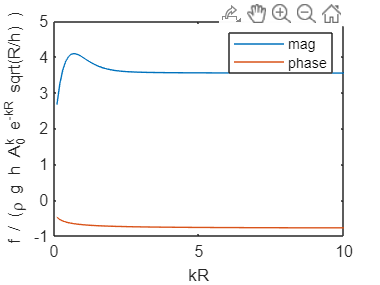

% the sqrt(h/R) term keeps it more similar for different h/R but is isn't
% quite equal because N0 has the 1+ term that doesn't have a kh in it
figure
plot(kR,abs(f_over_rho_g_h_A0k_exp_minus_kR)*sqrt(h_over_R),...
     kR,angle(f_over_rho_g_h_A0k_exp_minus_kR))
legend('mag','phase')
xlabel('kR')
ylabel('f / (\rho g h A_0^k e^{-kR} sqrt(R/h) )')

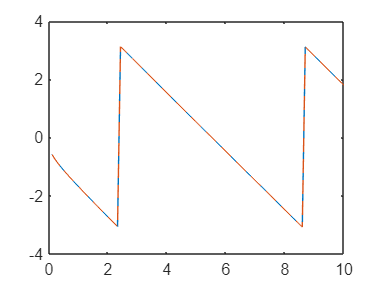

phase = angle( -1i * besselh(0, 2, kR) );
phase2 = wrapToPi(-pi/2 - angle( besselh(0, 1, kR) ));
figure
plot(kR,phase, kR,phase2,'--')